## 1.每个通道的条件差异显著时间点

% 每个通道的EC与EC0显著差异时间点
figure;
load('D:\\Ensemble coding\\data\\chanmap.mat','ChanMap');
for coil =1:96
    n = find(ChanMap==coil);
    subplot(10,10,n);
    group1 = squeeze(ECdata{9}(:,coil,:));
    group2 = squeeze(EC0data{9}(:,coil,:));
    % 假设数据已加载为group1和group2（均为140×91的矩阵）

    % 计算均值和标准误
    mean1 = mean(group1, 1);
    sem1 = std(group1, 0, 1) / sqrt(size(group1, 1));
    mean2 = mean(group2, 1);
    sem2 = std(group2, 0, 1) / sqrt(size(group2, 1));

    % 进行独立样本t检验
    alpha = 0.05;
    p_values = zeros(1, 91);
    for t = 1:91
        [~, p] = ttest2(group1(:, t), group2(:, t));
        p_values(t) = p;
    end
    significant = p_values < alpha;
    sig_x = find(significant);

    hold on;

    % 绘制均值线
    x = 1:91;
    plot(x, mean1, 'b', 'LineWidth', 1.5);
    plot(x, mean2, 'r', 'LineWidth', 1.5);

    % 添加误差带
    fill([x fliplr(x)], [mean1+sem1 fliplr(mean1-sem1)], 'b', ...
        'FaceAlpha', 0.3, 'EdgeColor', 'none');
    fill([x fliplr(x)], [mean2+sem2 fliplr(mean2-sem2)], 'r', ...
        'FaceAlpha', 0.3, 'EdgeColor', 'none');

    % 调整坐标轴以显示显著性标记
    % yl = ylim;
    % y_marker_pos = yl(1) - 0.05 * (yl(2) - yl(1)); % 标记位置在y轴下方
    % ylim([y_marker_pos - 0.5 * (yl(2)-yl(1)), yl(2)]);
    % 
    % % 标注显著差异的时间点
    % stem(sig_x, repmat(y_marker_pos, size(sig_x)), 'k^', 'MarkerFaceColor', 'k', ...
    %     'MarkerSize', 5, 'LineWidth', 1, 'Clipping', 'off');

    % 设置图形标签

    hold off;
    subtitle(sprintf('coil%d',coil));
end
%% 
subplot(10,10,100)
xlabel('Time Points');
ylabel('Mean ± SEM');
% legend({'Group 1 Mean', 'Group 2 Mean', '', '', 'Significant'}, ...
%     'Location', 'best');
sgtitle('Group Comparison with SEM and Significant Time Points');

## 2.单个通道条件差异显著时间点（每个ori）

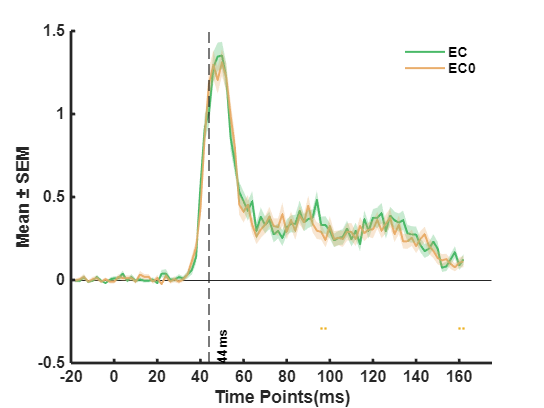

ori_coil = [9,18];
figure;

    group1 = squeeze(ECdata{ori_coil(1)}(:,ori_coil(2),:));
    group2 = squeeze(EC0data{ori_coil(1)}(:,ori_coil(2),:));
    % group1 = squeeze(mean(ECdata{ori}(:,coilselect,:),2));
    % group2 = squeeze(mean(EC0data{ori}(:,coilselect,:),2));

    % 假设数据已加载为group1和group2（均为140×91的矩阵）

    % 计算均值和标准误
    mean1 = mean(group1, 1);
    sem1 = std(group1, 0, 1) / sqrt(size(group1, 1));
    mean2 = mean(group2, 1);
    sem2 = std(group2, 0, 1) / sqrt(size(group2, 1));

    % 进行独立样本t检验
    alpha = 0.1;
    p_values = zeros(1, 91);
    % 显著性
    % for t = 1:91
    %     [~, p] = ttest2(mean(group1(:, t),2), mean(group2(:, t),2));
    %     p_values(t) = p;
    % end

    % bin的显著性
    for t = 3:89
        [~, p] = ttest2(mean(group1(:, (t-2):(t+2)),2), mean(group2(:, (t-2):(t+2)),2));
        p_values(t) = p;
    end

    % 累积显著性
    % for t = 1:91
    %     [~, p] = ttest2(mean(group1(:, 1:t),2), mean(group2(:, 1:t),2));
    %     p_values(t) = p;
    % end

    significant = p_values < alpha;
    sig_x = find(significant);
    sig_x = sig_x(sig_x>25);
    hold on;

    % 均值线
    x = 1:91;
    h1 = plot(x, mean1, 'b', 'LineWidth', 1.5,'Color',[74,185,104]/255);
    h2 = plot(x, mean2, 'r', 'LineWidth', 1.5,'Color',[233,173,107]/255);

    % 误差带
    fill([x fliplr(x)], [mean1+sem1 fliplr(mean1-sem1)], [74,185,104]/255, ...
        'FaceAlpha', 0.3, 'EdgeColor', 'none');
    fill([x fliplr(x)], [mean2+sem2 fliplr(mean2-sem2)], [233,173,107]/255, ...
        'FaceAlpha', 0.3, 'EdgeColor', 'none');

    yl = ylim;
    y_marker_pos = yl(1) - 0.05 * (yl(2) - yl(1));
    % ylim([y_marker_pos - 0.5 * (yl(2)-yl(1)), yl(2)]);
    % ylim([-0.4,1.6])

    % 显著差异的时间点
    stem(sig_x, repmat(y_marker_pos, size(sig_x)), '.', 'MarkerFaceColor', 'k', ...
        'MarkerSize', 5, 'LineWidth', 1, 'Clipping', 'off','LineStyle','none');
    xticks(0:10:90);
    xticklabels({'-20','0','20','40','60','80','100','120','140','160'});
    xlabel('Time Points(ms)');
    ylabel('Mean ± SEM');
    % xline(sig_x(1),'--','LineWidth',1.3);
    % text(sig_x(1) - 5, -0.2, sprintf('%dms',(sig_x(1)-10)*2), ...
    %     'Color', 'r', 'FontSize', 10, 'HorizontalAlignment', 'left','Rotation',90,'FontWeight','bold');
    xline(32,'--','LineWidth',1.3)
    text(33 + 2, -0.5, '44ms', ...
        'Color', 'k', 'FontSize', 10, 'HorizontalAlignment', 'left','Rotation',90,'FontWeight','bold');
legend([h1,h2],{'EC','EC0'},'Box','off');
% sgtitle('Group Comparison with SEM and Significant Time Points');
ax = gca;
ax.LineWidth = 2;
ax.FontSize = 12;
ax.FontWeight = 'bold';
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;
ax.XAxis.FontWeight = 'bold';

## 3.解码结果绘制

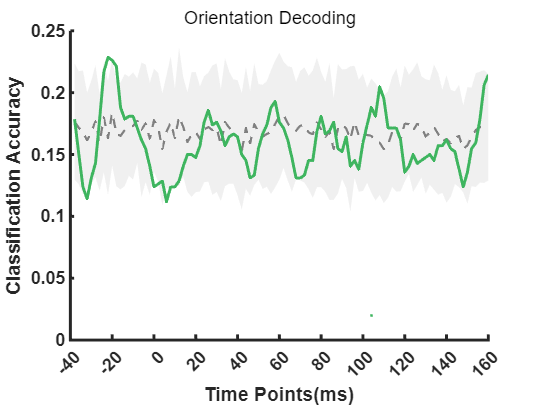

figure;

i = 1;
% MGV,MGnv,SG
colors = [62,181,95;233,173,107;120,158,175;142,50,40]/255;
% figure('Position', [100 100 1600 600]);
% for ori = 1:10
%     subplot(4,5,ori)
% 
%     % subplot(4,5,pre);
%     fileList = dir(sprintf('D:\\Ensembe plot\\Decoding\\orientation_SVMdata\\samepre\\EC0\\orientationSVM3_7day_preori%d.mat',ori));
%     load(fullfile(fileList.folder,fileList.name));

    % 计算显著性
    baseline_mean = mean(shuffle_acc);
    baseline_std = std(shuffle_acc);
    z_scores = (accuracy - baseline_mean) ./ baseline_std;
    p_values = 1 - normcdf(z_scores); % 单尾检验
    % [~, ~, ~, adj_p] = fdr_bh(p_values, 0.05);
    significant = p_values < 0.05;

    n_timepoints = length(accuracy);
    % figure('Position', [100 100 1600 600]);
    
    smoothaccuracy = smooth(accuracy);
    hold on
    % shuffle段
    x = 1:n_timepoints;
    fill([x fliplr(x)], [baseline_mean+baseline_std fliplr(baseline_mean-baseline_std)],...
        [0.8 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
    plot(x, baseline_mean, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 1.5);
    % smoothaccuracy(1:30) = smoothaccuracy(1:30)/1.3;
    plot(x, smoothaccuracy, 'b', 'LineWidth', 2,'Color',colors(i,:));

    % 显著点
    yl = ylim;
    % y_marker_pos = yl(1) - 0.05 * (yl(2) - yl(1)); % 标记位置在y轴下方
    y_marker_pos = 0.01+0.01*i;
    % ylim([0.14,0.2])
    sig_x = find(significant==1);
    sig_x = sig_x(sig_x>25&sig_x<80);
    sig_x = sig_x(1:end);
    % 标注显著差异的时间点
    stem(sig_x, repmat(y_marker_pos, size(sig_x)), '.', 'MarkerFaceColor', 'k', ...
        'MarkerSize', 5, 'LineWidth', 1, 'Clipping', 'off','LineStyle','none','MarkerEdgeColor',colors(i,:));
    % xline(sig_x(1),'--');
    % xline(33,'--')
    % text(sig_x(1) - 5, 0.02, sprintf('%dms',(sig_x(1)-10)*2), ...
    %     'Color', colors(1,:), 'FontSize', 10, 'HorizontalAlignment', 'left','Rotation',90);
    % text(33 + 2, 0.02, '46ms', ...
        % 'Color', 'k', 'FontSize', 10, 'HorizontalAlignment', 'left','Rotation',90);
    xticks(0:10:100);
    xticklabels({'-40','-20','0','20','40','60','80','100','120','140','160'});


    
    xlabel('Time Points(ms)');
    ylabel('Classification Accuracy');
    % legend({'Shuffle Baseline ±1σ', 'Shuffle Mean', 'Actual Accuracy', 'Significant Points'},...
    %         'Location', 'northwest');
    
% end
sgtitle('Orientation Decoding')

ax = gca;
ax.LineWidth = 2;
ax.FontSize = 12;
ax.FontWeight = 'bold';
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;
ax.XAxis.FontWeight = 'bold';

## 4.不同朝向与前一张朝向Pattern绘制

for oripre = 1:18
    figure;
    for ori = 1:18
        subplot(4,5,ori);
        hold on
        for pattern = 1:3
            
            if ~isempty(All_data_pre{pattern,ori,oripre})
                plot(squmean(All_data_pre{pattern,ori,oripre}(:,24,:),1));
            end
        end
        xticks(0:10:80);
        xticklabels({'0','20','40','60','80','100','120','140','160'});
        hold off
        subtitle(sprintf('ori%d',ori));
    end
    sgtitle(sprintf('pre ori%d',oripre));
end

未定义变量 'All_data_pre'。

figure;
load('D:\\Ensemble coding\\data\\chanmap.mat','ChanMap');
for coil =1:96
    n = find(ChanMap==coil);
    subplot(10,10,n);
    hold on;
    for pattern = 1:3
        plot(squmean(All_data_pre{pattern,9,1}(:,coil,:),1));
    end
    hold off
end